## Settings for simulink model initialization and data analysis

close all
clear all
clc
pm_addunit('percent', 0.01, '1');
options = bodeoptions;
options.FreqUnits = 'Hz';
simlength = 3.25;

## Grid Emulator Settings

grid_emulator;

## AFE Settings and Initialization

### Switching frequencies, sampling time and deadtime

fPWM_AFE = 4e3;
tPWM_AFE = 1/fPWM_AFE;

dead_time_AFE = 0;
delay_pwm = 0;
delayAFE_modB=2*pi*fPWM_AFE*delay_pwm; 
delayAFE_modA=0;
delayAFE_modC=0;

ts_afe = 1/fPWM_AFE/2; % Sampling time of the control AFE as well as INVERTER
tc = ts_afe/100;

s=tf('s');
z_afe=tf('z',ts_afe);

t_misura = simlength;
Nc = ceil(t_misura/tc);
Ns_afe = ceil(t_misura/ts_afe);


### FRT Settings

#### FRT, and other fault timing settings

test_index    = 25;
test_subindex = 4;

asymmetric_error_type = 0;  
% 0 -> Variant C, two phase, 
% 1 -> Variant D, single phase

start_time_grid_switch_open = 1e3;
start_time_LVRT = 2.0;
time_start_motor_control = 0.035;

time_aux_power_supply_fault = 1e3;
time_phase_fault = 1e3;
start_load = 0.25;


#### FRT gain factor for grid support

settle_time = 0.15;
k_frt_ref = 2;

#### Reactive current limits for grid support


i_grid_pos_eta_lim = 1;
i_grid_neg_xi_lim = 0.5;
i_grid_neg_eta_lim = 0.5;


#### Reactive current Limits - Red. Dyn. grid support

i_grid_pos_eta_red_lim = 0.1;
i_grid_neg_eta_red_lim = 0.1;
i_grid_neg_xi_red_lim = 0.1;


#### Grid voltage derivate implemented with double integrator observer

Aso = [0 1; 0 0];
Asod = eye(2)+Aso*ts_afe;
Cso = [1 0];
p2place = exp([-100 -500]*ts_afe);
Kd = (acker(Asod',Cso',p2place))';
l1 = Kd(1)

l1 =    0.073009136692643

l2 = Kd(2)

l2 =    6.020984169566646

#### Grid fault generator 

grid_fault_generator;

### Current sensor endscale, and quantization

Imax_adc = 1049.835;
CurrentQuantization = Imax_adc/2^11;

### Voltage sensor endscale, and quantization

Umax_adc = 1500;
VoltageQuantization = Umax_adc/2^11;

### DClink, and dclink-brake parameters

Vdc_ref = 1070; % DClink voltage reference
Rprecharge = 1; % Resistance of the DClink pre-charge circuit
Pload = 250e3;
Rbrake = 2.5;
CFi = 900e-6*8;

### LCL switching filter

LFu1_AFE = 0.5e-3;
RLFu1_AFE = 157*0.05*LFu1_AFE;
LFu1_AFE_0 = LFu1_AFE;
RLFu1_AFE_0 = RLFu1_AFE/3;
CFu = (100e-6*2);
RCFu = (50e-3);

### DClink voltage control parameters

Vdc_nom = Vdc_bez;
Vdc_norm_ref = Vdc_ref/Vdc_nom;
kp_vs = 0.85;
ki_vs = 35;

### AFE current control parameters

#### Resonant PI

kp_afe = 0.6;
ki_afe = 45;
delta = 0.05;
res = s/(s^2 + 2*delta*omega_grid_nom*s + (omega_grid_nom)^2);

Ares = [0 1; -omega_grid_nom^2 -2*delta*omega_grid_nom];
Bres = [0; 1];
Cres = [0 1];
Aresd = eye(2) + Ares*ts_afe;
Bresd = Bres*ts_afe;
Cresd = Cres;

### Grid Normalization Factors

Vgrid_phase_normalization_factor = Vphase2*sqrt(2);
pll_i1 = 80;
pll_p = 1;
Vmax_ff = 1.1;
Igrid_phase_normalization_factor = 250e3/Vphase2/3/0.9*sqrt(2);
ixi_pos_ref_lim = 1.4;
ieta_pos_ref_lim = 1.0;
ieta_neg_ref_lim = 0.5;

### Double Integrator Observer for PLL

Arso = [0 1; 0 0];
Crso = [1 0];
omega_rso = 2*pi*50;
polesrso = [-1 -4]*omega_rso;
Lrso = acker(Arso',Crso',polesrso)';
Adrso = eye(2) + Arso*ts_afe;
polesdrso = exp(ts_afe*polesrso);
Ldrso = acker(Adrso',Crso',polesdrso)';

### IGBT and snubber data

Ron = 3.5e-3;
Csnubber = 0.15e-6;
Rsnubber = 2200;
Vgamma = 1.6;

### Reactive current control gains

kp_rc_grid = 0.1;
ki_rc_grid = 2;

kp_rc_pos_grid = 0.35;
ki_rc_pos_grid = 35;
kp_rc_neg_grid = 0.35;
ki_rc_neg_grid = 35;

### Settings for First Order Low Pass Filters

#### LPF 50Hz in state space (for initialization)

fcut = 50;
fof = 1/(s/(2*pi*fcut)+1);
[nfof, dfof] = tfdata(fof,'v');
[nfofd, dfofd]=tfdata(c2d(fof,ts_afe),'v');
fof_z = tf(nfofd,dfofd,ts_afe,'Variable','z');
[A,B,C,D] = tf2ss(nfofd,dfofd);
LVRT_flt_ss = ss(A,B,C,D,ts_afe);
[A,B,C,D] = tf2ss(nfof,dfof);
LVRT_flt_ss_c = ss(A,B,C,D);

#### LPF 161Hz

fcut_161Hz_flt = 161;
g0_161Hz = fcut_161Hz_flt * ts_afe * 2*pi;
g1_161Hz = 1 - g0_161Hz;

#### LPF 500Hz

fcut_500Hz_flt = 500;
g0_500Hz = fcut_500Hz_flt * ts_afe * 2*pi;
g1_500Hz = 1 - g0_500Hz;

#### LPF 75Hz

fcut_75Hz_flt = 75;
g0_75Hz = fcut_75Hz_flt * ts_afe * 2*pi;
g1_75Hz = 1 - g0_75Hz;

#### LPF 50Hz

fcut_50Hz_flt = 50;
g0_50Hz = fcut_50Hz_flt * ts_afe * 2*pi;
g1_50Hz = 1 - g0_50Hz;

#### LPF 10Hz

fcut_10Hz_flt = 10;
g0_10Hz = fcut_10Hz_flt * ts_afe * 2*pi;
g1_10Hz = 1 - g0_10Hz;

#### LPF 4Hz

fcut_4Hz_flt = 4;
g0_4Hz = fcut_4Hz_flt * ts_afe * 2*pi;
g1_4Hz = 1 - g0_4Hz;

#### LPF 1Hz

fcut_1Hz_flt = 1;
g0_1Hz = fcut_1Hz_flt * ts_afe * 2*pi;
g1_1Hz = 1 - g0_1Hz;

#### LPF 0.2Hz

fcut_0Hz2_flt = 0.2;
g0_0Hz2 = fcut_0Hz2_flt * ts_afe * 2*pi;
g1_0Hz2 = 1 - g0_0Hz2;

### Settings for RMS calculus

rms_perios = 1;
n1 = rms_perios/f_grid/ts_afe;
rms_perios = 10;
n10 = rms_perios/f_grid/ts_afe;

### Online time domain sequence calculator

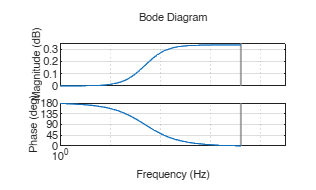

w_grid = 2*pi*f_grid;
apf = (s/w_grid-1)/(s/w_grid+1);
[napfd, dapfd]=tfdata(c2d(apf,ts_afe),'v');
apf_z = tf(napfd,dapfd,ts_afe,'Variable','z');
[A,B,C,D] = tf2ss(napfd,dapfd);
ap_flt_ss = ss(A,B,C,D,ts_afe);
figure;
bode(ap_flt_ss,options);
grid on

## INVERTER Settings and Initialization

### Mode of operation

motor_torque_mode = 1; % system uses torque curve for wind application

### Switching frequencies, sampling time and deadtime

fPWM_INV = fPWM_AFE;
dead_time_INV = 0;
delayINV_modA = 0;
pwm_out_lim = 1;
use_psm_encoder = 0;

ts_inv = 1/fPWM_INV/2;
t_measure = simlength;
Ns_inv = floor(t_measure/ts_inv);
s=tf('s');
z=tf('z',ts_inv);


### MOTOR Selection from Library

number_of_modules = 2;
run('generic_1M5W_pmsm');

unom_rms =      2.553104575163399e+02

vg_dclink =      9.437980595572818e+02

vg_phph_rms =      6.673660079836591e+02

run('generic_1M5W_torque_curve');
b = tau_bez/omega_m_bez*1.25;

psm = psm_calculus();

Permanent Magnet Synchronous Machine: WindGen
PSM Normalization Voltage Factor: 365.8 V | PSM Normalization Current Factor: 486.0 A
Per-System Direct Axis Inductance: 0.00624 H
Per-System Quadrature Axis Inductance: 0.00756 H
---------------------------


n_sys = psm.number_of_systems;

LFi = 40e-6;
RLFi = 5e-3;


### Simulation parameters: speed reference, load torque in motor mode

omega_m_sim = omega_m_bez;
omega_sim = omega_m_sim*number_poles/2;
tau_load_sim = tau_bez; %N*m
b_square = 0;


### Luenberger Observer

Aso = [1 ts_inv; 0 1];
Cso = [1 0];
p2place = exp([-10 -50]*ts_inv);
K = (acker(Aso',Cso',p2place))';
kg = K(1)

kg =    0.007479728452025

kw = K(2)

kw =    0.062266169303271

### Rotor speed observer with load estimator

A = [0 1 0; 0 0 -1/Jm_norm; 0 0 0];
Alo = eye(3) + A*ts_inv;
Blo = [0; ts_inv/Jm_norm; 0];
Clo = [1 0 0];
p3place = exp([-1 -5 -25]*125*ts_inv);
Klo = (acker(Alo',Clo',p3place))';
luenberger_l1 = Klo(1);
luenberger_l2 = Klo(2);
luenberger_l3 = Klo(3);
omega_flt_fcut = 10;
% phase_compensation_omega = -pi/2-pi/12; % for motor mode
phase_compensation_omega = 0; % for generator mode


### Control settings

id_lim = 0.35;

#### rotor speed control

kp_w = 0.25;
ki_w = 8;
iq_lim = 1.6;

#### current control

kp_i = 0.5;
ki_i = 18;
kp_id = kp_i;
ki_id = ki_i;
kp_iq = kp_i;
ki_iq = ki_i;
CTRPIFF_CLIP_RELEASE = 0.001;

#### Field Weakening Control 

kp_fw = 0.05;
ki_fw = 1.8;


#### BEMF observer

emf_fb_p = 0.4;
emf_p = emf_fb_p*4/10;

emf_fb_p_ccaller_1 = emf_fb_p;
emf_p_ccaller_1 = emf_fb_p_ccaller_1*4/10;

emf_fb_p_ccaller_2 = emf_fb_p;
emf_p_ccaller_2 = emf_fb_p_ccaller_2*4/10;

#### Speed obserfer filter LPF 10Hz

fcut_10Hz_flt = 10;
omega_flt_g0 = fcut_10Hz_flt * ts_inv * 2*pi;
omega_flt_g1 = 1 - omega_flt_g0;

#### Motor Voltage to Udc Scaling

motorc_m_scale = 2/3*Vdc_bez/ubez;



## C-Caller Settings

model = 'afe_rst_inv_psm_distributed_control_two_delays';
open_system(model);
Simulink.importExternalCTypes(model,'Names',{'mavgflt_output_t'});
Simulink.importExternalCTypes(model,'Names',{'bemf_obsv_output_t'});
Simulink.importExternalCTypes(model,'Names',{'bemf_obsv_load_est_output_t'});
Simulink.importExternalCTypes(model,'Names',{'dqvector_pi_output_t'});
Simulink.importExternalCTypes(model,'Names',{'sv_pwm_output_t'});
Simulink.importExternalCTypes(model,'Names',{'global_state_machine_output_t'});


## Remove Scopes Opening Automatically

% shh = get(0,'ShowHiddenHandles');
% set(0,'ShowHiddenHandles','On');
% hscope = findobj(0,'Type','Figure','Tag','SIMULINK_SIMSCOPE_FIGURE');
% close(hscope);
% set(0,'ShowHiddenHandles',shh);